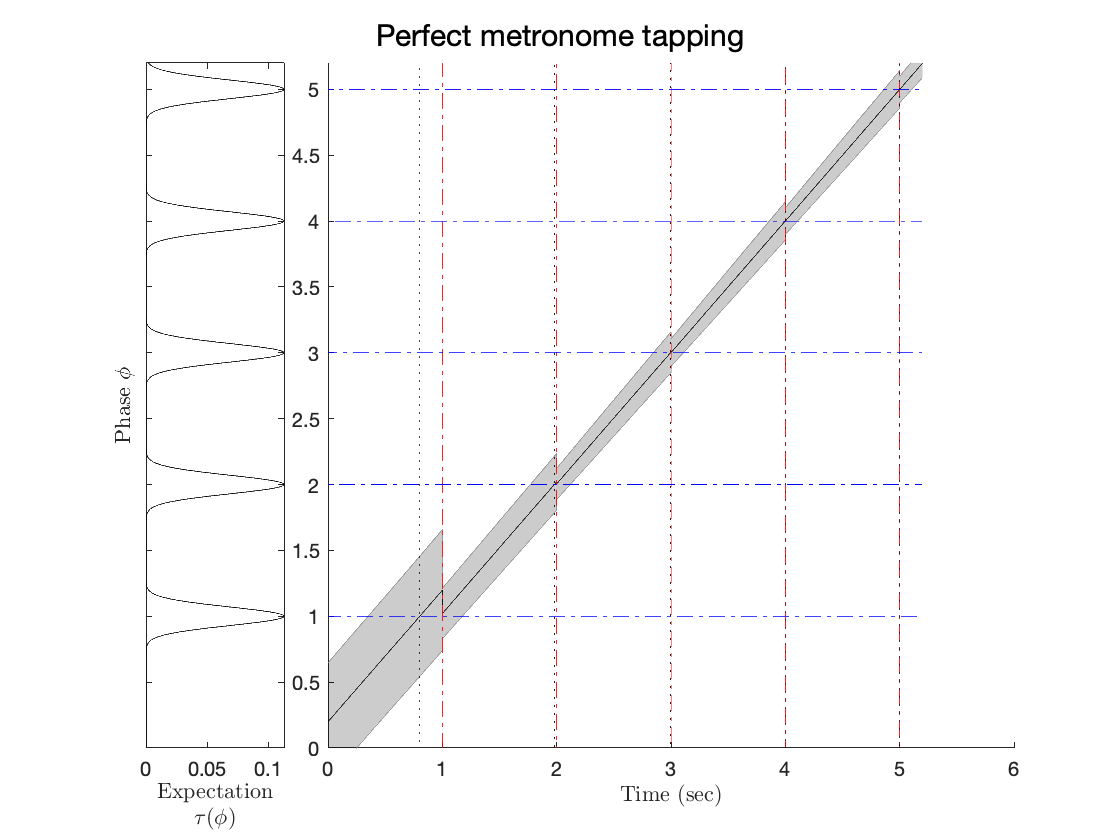

% (C) Jonathan Cannon, MIT, 2020

n_events = 5;
event_times = 1:n_events;

params = PIPPET_params(...
    'lambda_unit', 0.02,...
    'means_unit', [1],...
    'variance_unit', [.005],...
    'event_times',[.25, .5,.75, 1],...
    'lambda_unit', [.02],...
    'lambda_0', 0,...
    'expected_cycles', n_events,...
    'expected_period', 1,...
    'V_0', .05,...
    'phibar_0', .2,...
    'event_times', event_times, ...
    'tapping', true,...
    'title', 'Perfect metronome tapping');
[phibar_list, V_list] = run_PIPPET(params);

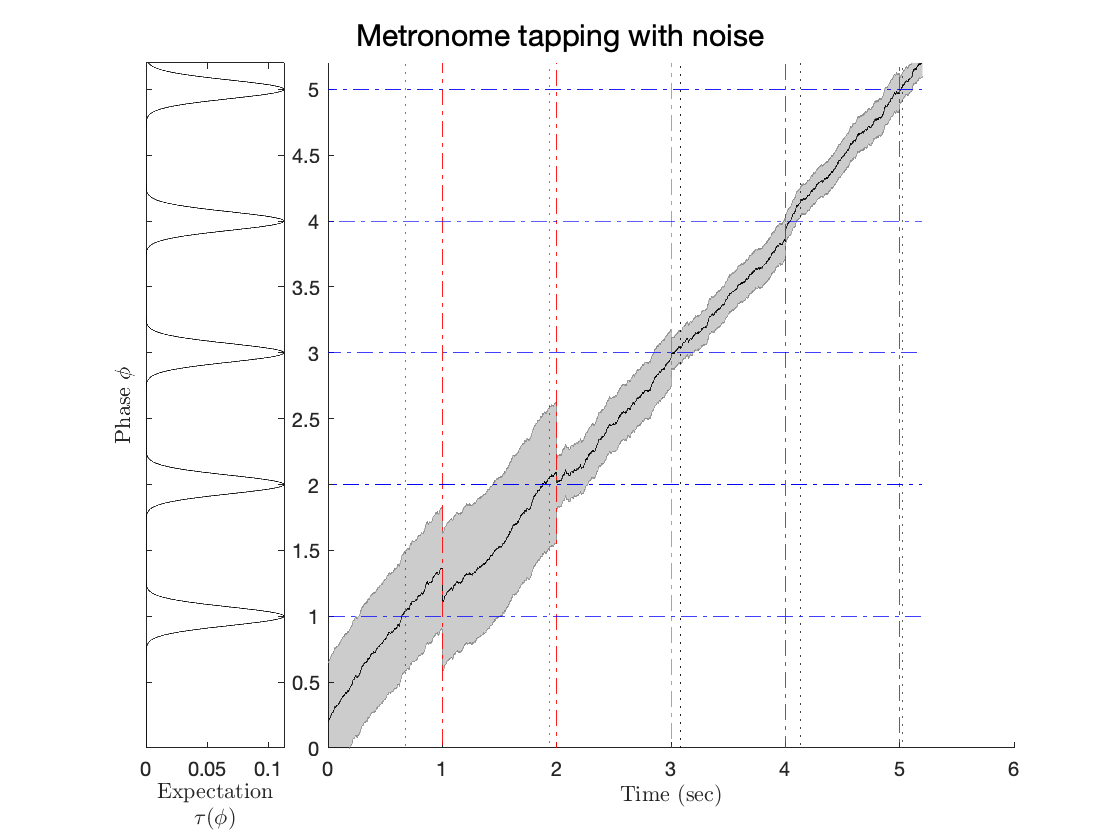



params2 = PIPPET_params(...
    'lambda_unit', 0.02,...
    'means_unit', [1],...
    'variance_unit', [.005],...
    'event_times',[.25, .5,.75, 1],...
    'lambda_unit', [.02],...
    'lambda_0', 0,...
    'expected_cycles', n_events,...
    'expected_period', 1,...
    'V_0', .05,...
    'phibar_0', .2,...
    'eta_phi', .1,...
    'event_times', event_times, ...
    'tapping', true,...
    'title', 'Metronome tapping with noise');
[phibar_list, V_list] = run_PIPPET(params2);

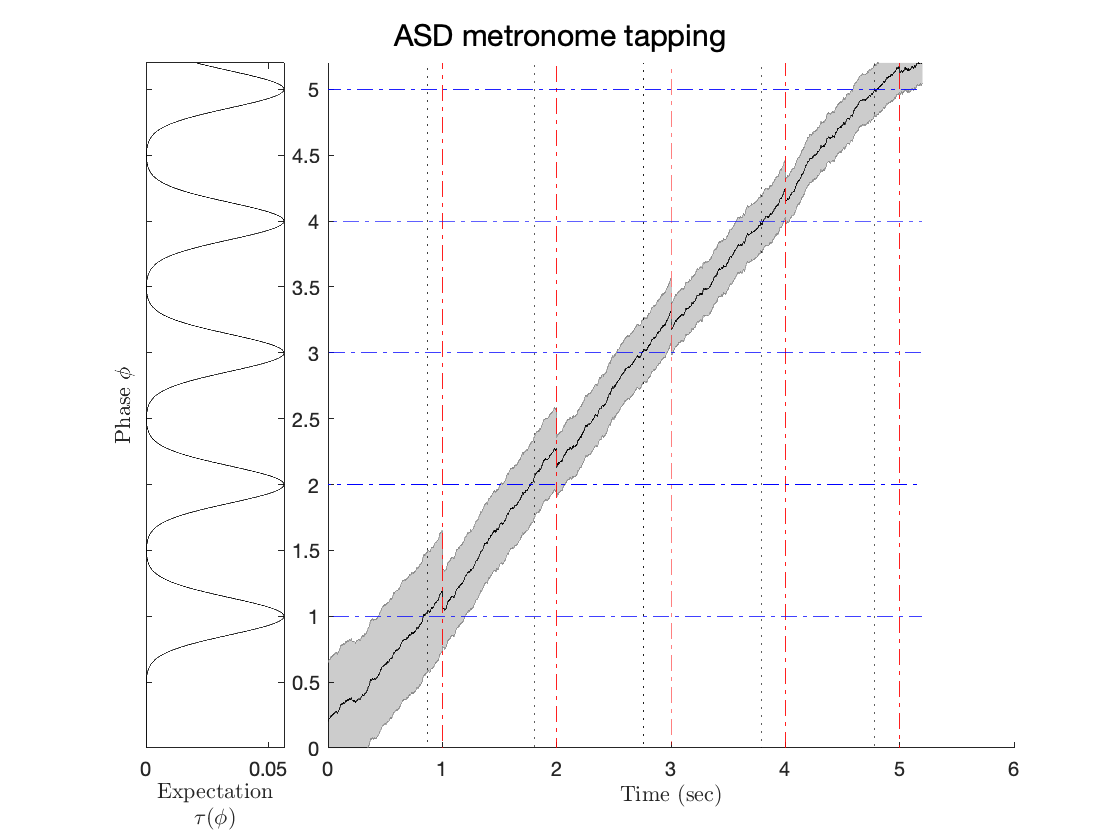

phibar_list =     0.2000    0.2049    0.2079    0.2130    0.2101    0.2121    0.2148    0.2154    0.2180    0.2211    0.2231    0.2282    0.2255    0.2273    0.2242    0.2244    0.2248    0.2255    0.2248    0.2285    0.2302    0.2363    0.2377    0.2406    0.2430    0.2450    0.2462    0.2481    0.2413    0.2399    0.2444    0.2417    0.2471    0.2444    0.2494    0.2500    0.2464    0.2478    0.2485    0.2531    0.2553    0.2579    0.2564    0.2517    0.2556    0.2574    0.2555    0.2605    0.2568    0.2595


V_list =     0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501



params3 = PIPPET_params(...
    'lambda_unit', 0.02,...
    'means_unit', [1],...
    'variance_unit', [.02],...
    'event_times',[.25, .5,.75, 1],...
    'lambda_unit', [.02],...
    'lambda_0', 0,...
    'expected_cycles', n_events,...
    'expected_period', 1,...
    'V_0', .05,...
    'phibar_0', .2,...
    'eta_phi', .1,...
    'event_times', event_times, ...
    'tapping', true,...
    'title', 'ASD metronome tapping');
[phibar_list, V_list] = run_PIPPET(params3)



%Tapping autocorr

n_events = 1000;
tap_thresh = .7;
event_times = 1:n_events;

expectation_variance_list = [.005, .02];
condition_list = {'NT', 'ASD'};

async_list = {[],[]};
AC_list = {[],[]};
alpha_list = [0,0];

for condition = 1:length(expectation_variance_list)
    params = PIPPET_params(...
        'means_unit', [1],...
        'variance_unit', [expectation_variance_list(condition)],...
        'lambda_unit', [.02],...
        'lambda_0', 0,...
        'expected_cycles', n_events,...
        'expected_period', 1,...
        'event_times', event_times,...
        'display', false,...
        'eta_phi', .05,...
        'tapping', true,...
        'title', 'Tap along');
    [phibar_list, V_list, tap_times] = run_PIPPET(params);

    async =  tap_times(1:length(event_times)) - event_times;
    async_list{condition} = async;
    AC_list{condition} = autocorr(async);
    
end

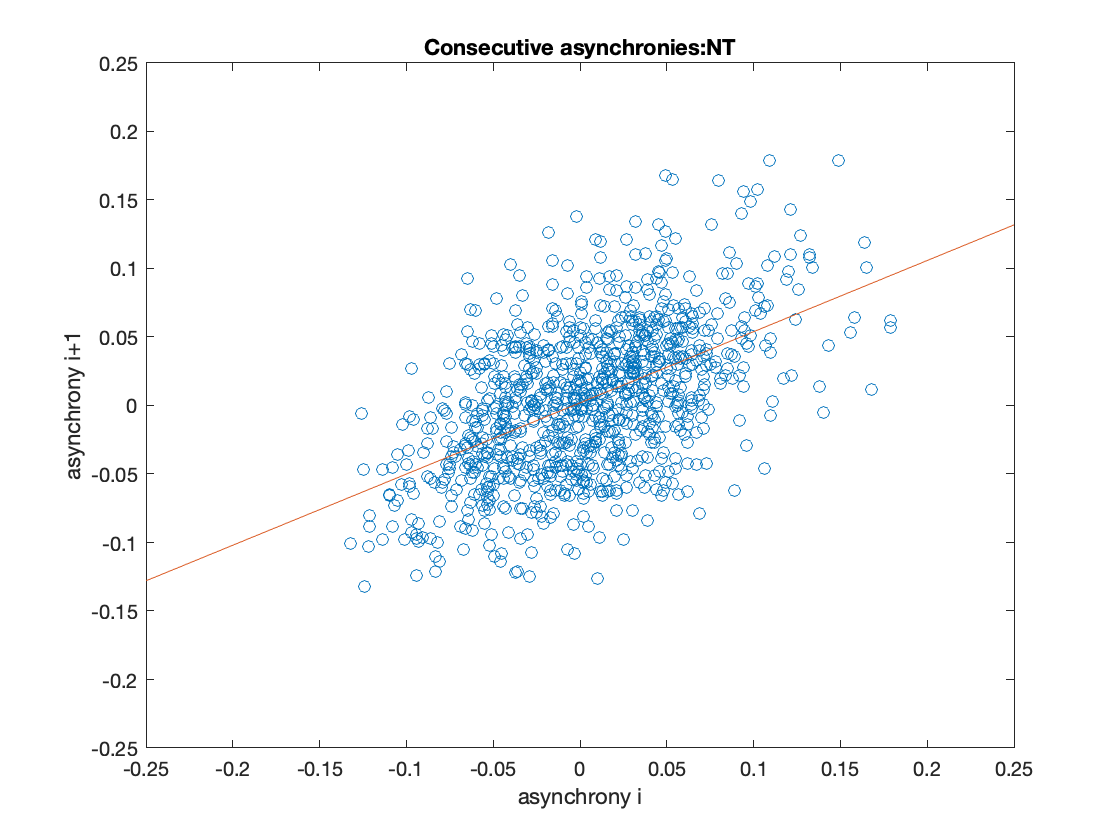

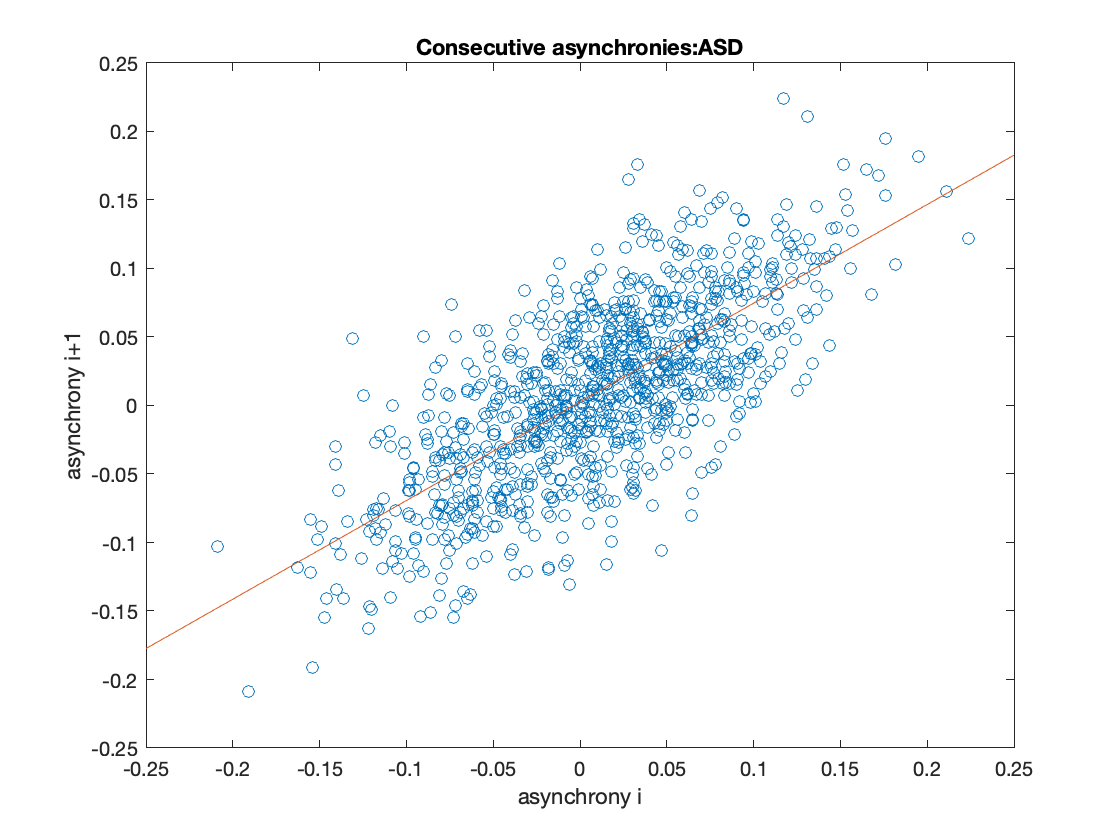



for condition = 1:length(condition_list)
    figure()
    P = polyfit(async_list{condition}(1:end-1),async_list{condition}(2:end),1);
    plot(async_list{condition}(1:end-1), async_list{condition}(2:end), 'o')
    hold on
    plot([-.25, .25], P(1)*[-.25, .25]+P(2));
    title(strcat('Consecutive asynchronies: ', condition_list{condition}));
    xlim([-.25, .25])
    ylim([-.25, .25])
    xlabel('asynchrony i')
    ylabel('asynchrony i+1')
end

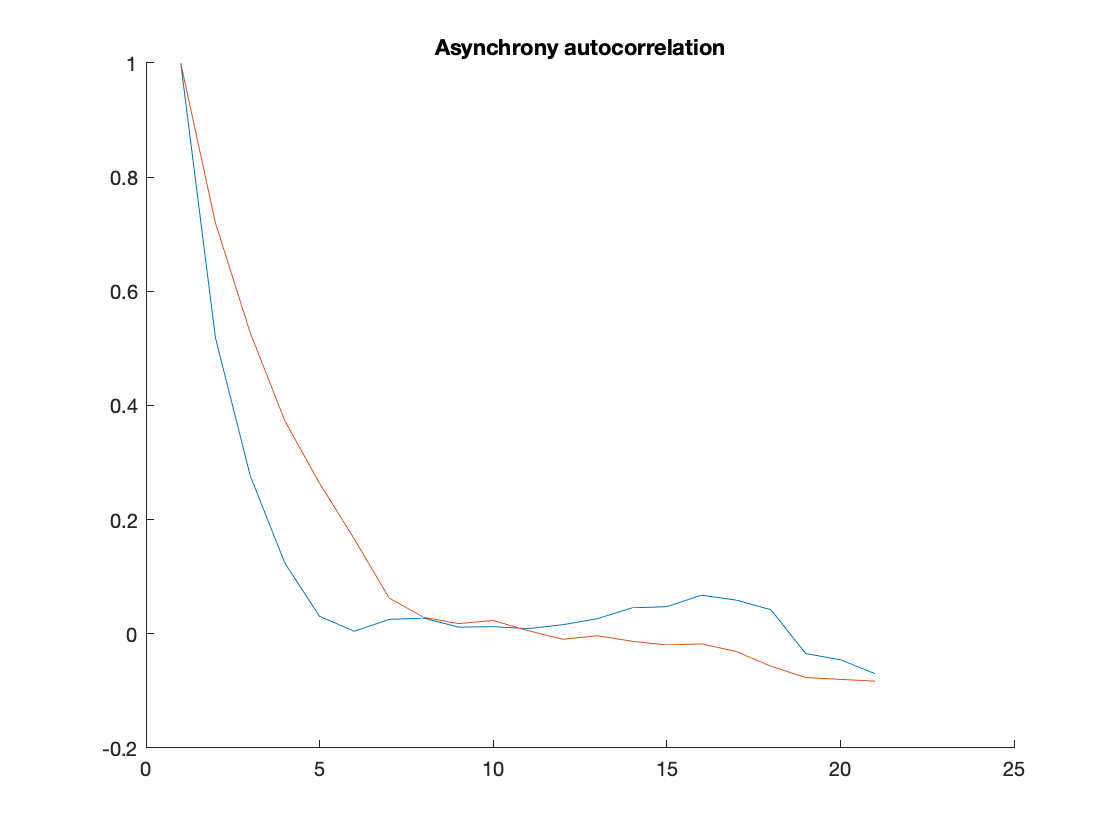


figure()
hold on
for condition = 1:length(expectation_variance_list)
    
    plot(AC_list{condition})
end
title('Asynchrony autocorrelation')

Make a movie of PIPPET in action


event_time = 0.55;
params = PIPPET_params(...
    'means_unit', [.5],...
    'variance_unit', [.0005],...
    'expected_period', .5,...
    'expected_cycles', 1,...
    'event_times', [event_time], ...
    'lambda_unit', .1,...
    'lambda_0', .02, ...
    'V_0', .0005, ...
    'tmax', event_time*2);

[phibar_list, V_list] = run_PIPPET(params);


make_PIPPET_video('PIPPET_late_continue', params, phibar_list, V_list, [0,.7], [-5,20], false, 'MPEG-4')


event_time = 0.45;
params = PIPPET_params(...
    'means_unit', [.5],...
    'variance_unit', [.0005],...
    'expected_period', .5,...
    'expected_cycles', 1,...
    'event_times', [event_time], ...
    'lambda_unit', .1,...
    'lambda_0', .02, ...
    'V_0', .0005, ...
    'tmax', event_time);

[phibar_list, V_list] = run_PIPPET(params);


make_PIPPET_video('PIPPET_early', params, phibar_list, V_list, [0,.7], [-5,20], true, 'MPEG-4')


event_time = 0.55;
params = PIPPET_params(...
    'means_unit', [.5],...
    'variance_unit', [.0005],...
    'expected_period', .5,...
    'expected_cycles', 1,...
    'event_times', [event_time], ...
    'lambda_unit', .1,...
    'lambda_0', .02, ...
    'V_0', .0005, ...
    'tmax', event_time);

[phibar_list, V_list] = run_PIPPET(params);


make_PIPPET_video('PIPPET_late', params, phibar_list, V_list, [0,.7], [-5,20], true, 'MPEG-4')

event_time = 0.38;
params = PIPPET_params(...
    'means_unit', [.5],...
    'variance_unit', [.0005],...
    'expected_period', .5,...
    'expected_cycles', 1,...
    'event_times', [event_time], ...
    'lambda_unit', .1,...
    'lambda_0', .02, ...
    'V_0', .0005, ...
    'tmax', event_time);

[phibar_list, V_list] = run_PIPPET(params);


make_PIPPET_video('PIPPET_very_early', params, phibar_list, V_list, [0,.7], [-5,20], true, 'MPEG-4')


event_time = 0.3;
params = PIPPET_params(...
    'means_unit', [.5],...
    'variance_unit', [.0005],...
    'expected_period', .5,...
    'expected_cycles', 1,...
    'event_times', [event_time], ...
    'lambda_unit', .1,...
    'lambda_0', .02, ...
    'V_0', .0005, ...
    'tmax', event_time*2);

[phibar_list, V_list] = run_PIPPET(params);


make_PIPPET_video('PIPPET_too_early', params, phibar_list, V_list, [0,.7], [-5,20], false, 'MPEG-4')


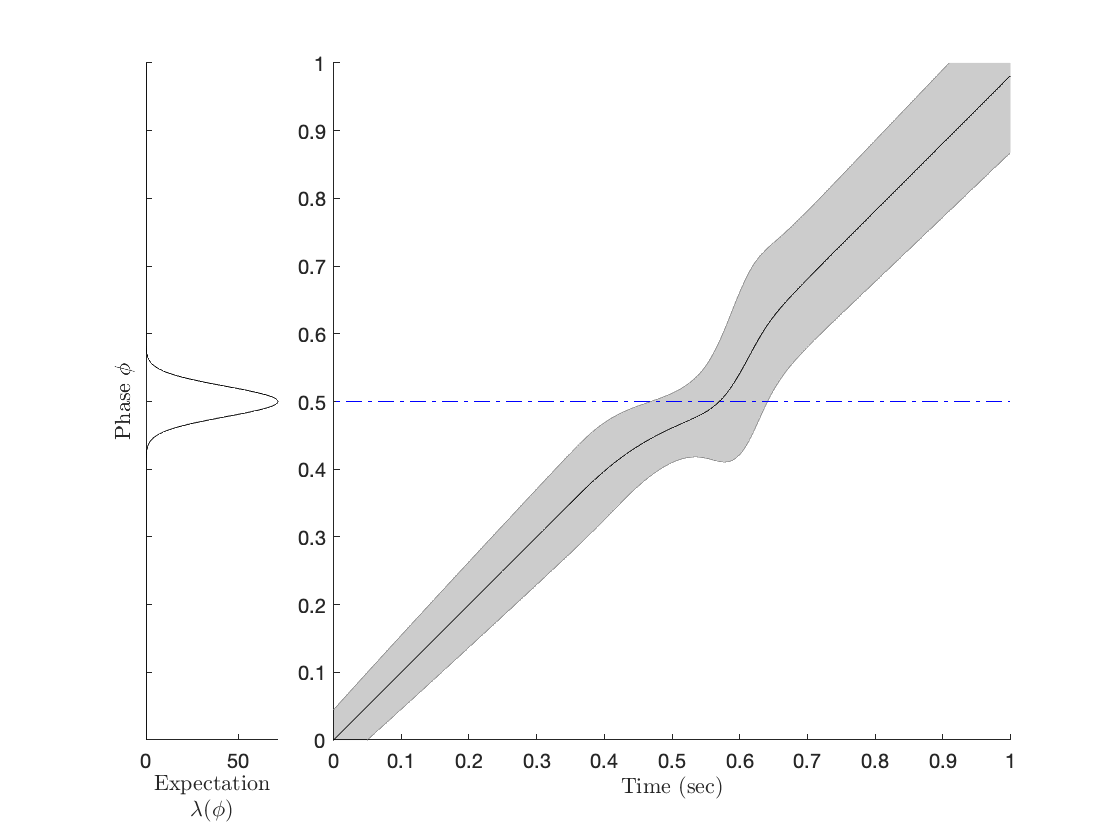



params = PIPPET_params(...
    'means_unit', [.5],...
    'variance_unit', [.0005],...
    'expected_period', .5,...
    'expected_cycles', 1,...
    'event_times', [], ...
    'lambda_unit', 4,...
    'lambda_0', .02, ...
    'V_0', .0005, ...
    'tmax', 1);

[phibar_list, V_list] = run_PIPPET(params);

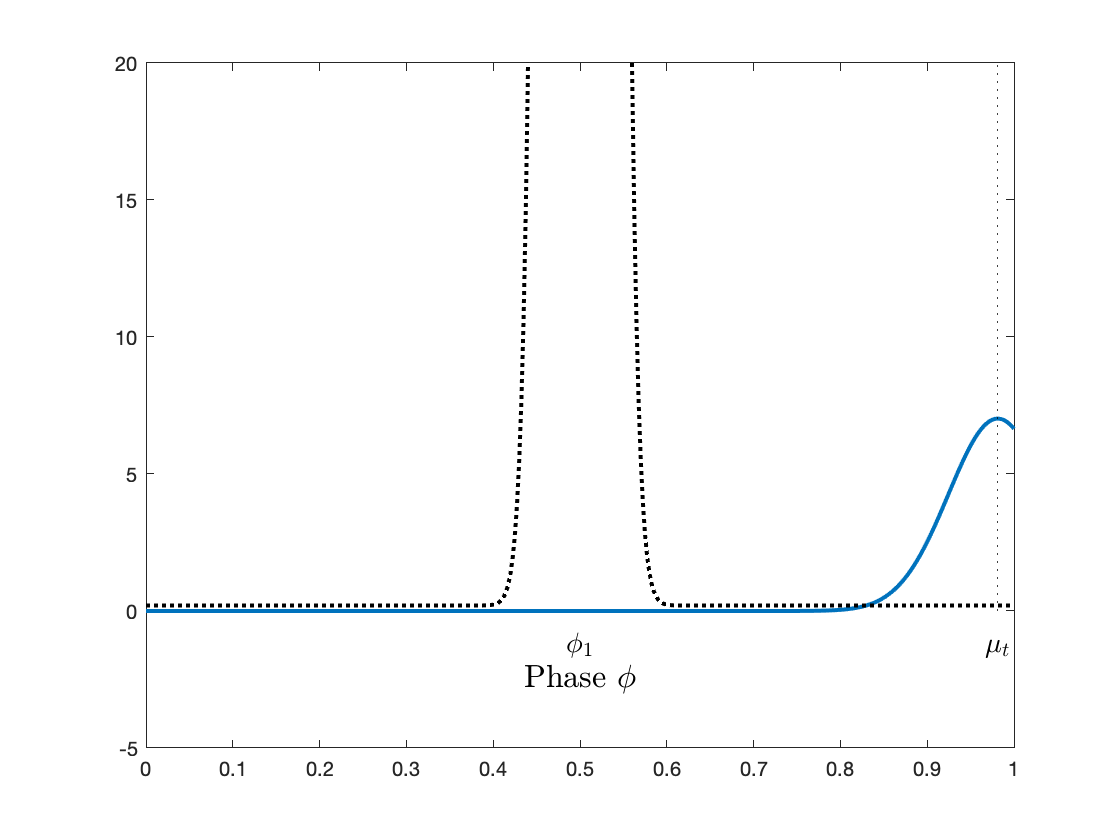


make_PIPPET_video('PIPPET_omission', params, phibar_list, V_list, [0,1], [-5,20], false, 'MPEG-4')

TICS rhythm example

stretch = 1;
sp = sound_params();

components_path = 'stimulus_components/'

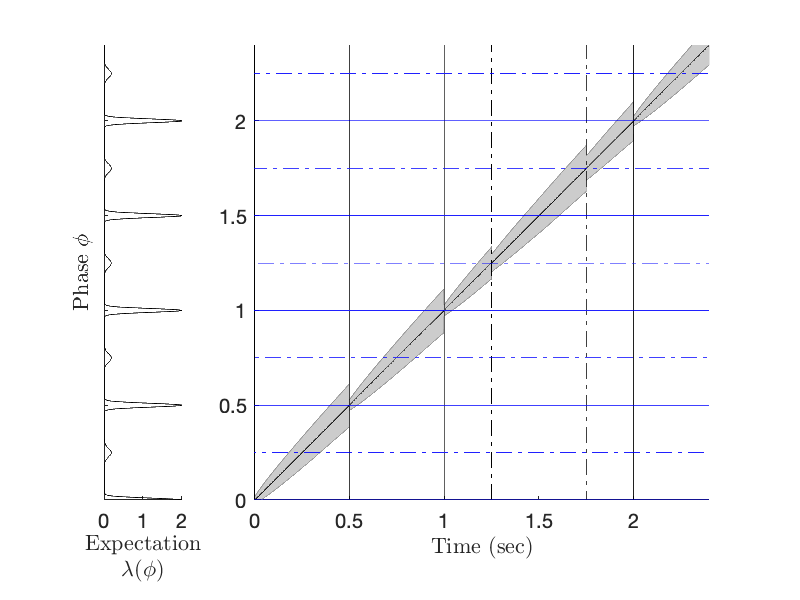


event_times = [0, .5, 1, 1.25, 1.75, 2];
highlight_event_indices = [1,1,1,0,0,1];
highlight_expectations = [1,0];

params = PIPPET_params(...
    'means_unit', [0, .25],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'sigma', .08,...
    'expected_cycles', 6,...
    'expected_period', .5,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'tmax', 2.4);

[phibar_list, V_list] = run_PIPPET(params);
set(gcf,'position',[560   528   400   300])

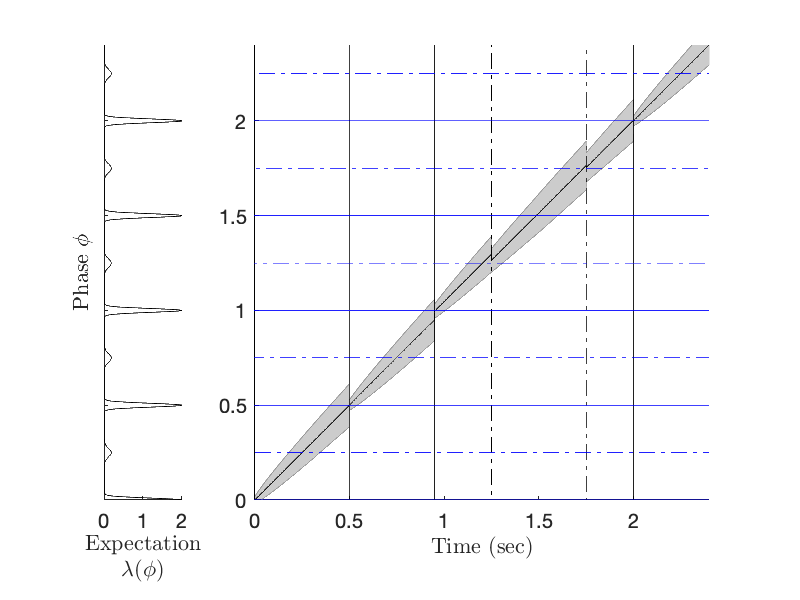


    times_w_lead = [0, .5, 1, 1.5, event_times+2];
    identities = [sp.beep_index*ones(1,4), sp.standard_index*ones(size(event_times))];
    snd = stim_maker_etime(stretch*times_w_lead, identities, sp);
    audiowrite('sounds/TIC_rhythm.wav', snd, 44100);


event_times = [0, .5, .95, 1.25, 1.75, 2];

params = PIPPET_params(...
    'means_unit', [0, .25],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'sigma', .08,...
    'expected_cycles', 6,...
    'expected_period', .5,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'tmax', 2.4);

[phibar_list, V_list] = run_PIPPET(params);
set(gcf,'position',[560   528   400   300])

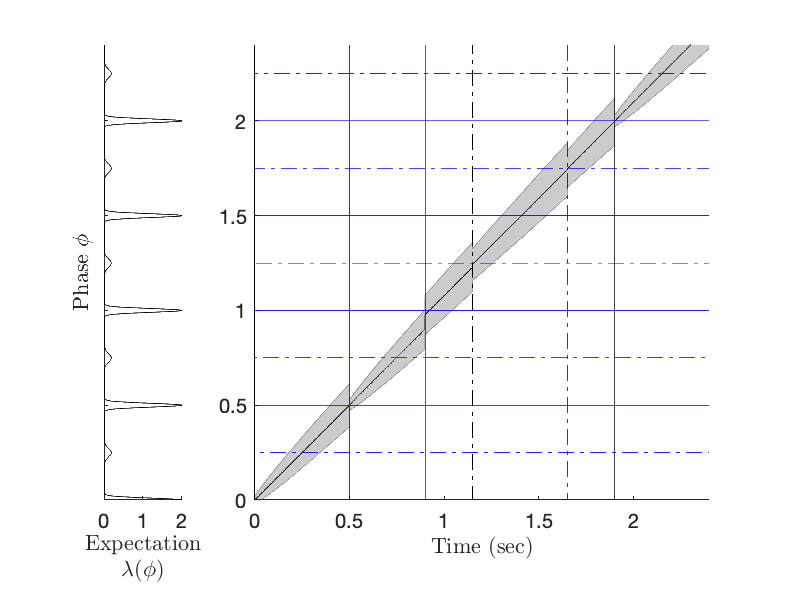


    times_w_lead = [0, .5, 1, 1.5, event_times+2];
    identities = [sp.beep_index*ones(1,4), sp.standard_index*ones(size(event_times))];
    snd = stim_maker_etime(stretch*times_w_lead, identities, sp);
    audiowrite('sounds/TIC_rhythm_event.wav', snd, 44100);

event_times = [0, .5, 1, 1.25, 1.75, 2];

event_times(3:end) = event_times(3:end)-.1;
params = PIPPET_params(...
    'means_unit', [0, .25],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'sigma', .08,...
    'expected_cycles', 6,...
    'expected_period', .5,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'tmax', 2.4);

[phibar_list, V_list] = run_PIPPET(params);
set(gcf,'position',[560   528   400   300])


times_w_lead = [0, .5, 1, 1.5, event_times+2];
    identities = [sp.beep_index*ones(1,4), sp.standard_index*ones(size(event_times))];
    snd = stim_maker_etime(stretch*times_w_lead, identities, sp);
    audiowrite('sounds/TIC_rhythm_phase.wav', snd, 44100);
